epsilon = 0.08;
a = 1;
b = 0.2

b = 0.2000

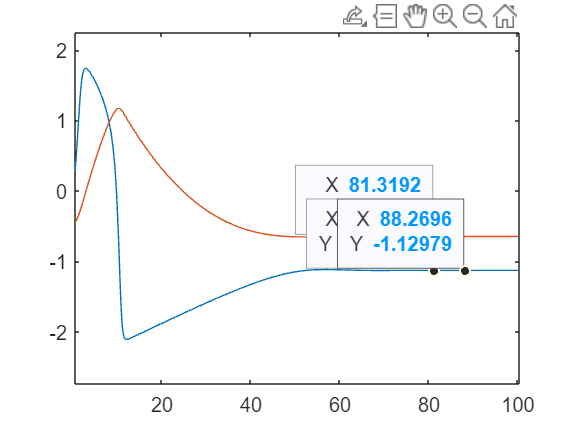


dvdt = @(v,w) v - (1/3)*v^3 - w;
dwdt = @(v,w) epsilon*(v + a - b*w);

dxdt = @(t,x)[dvdt(x(1),x(2));
    dwdt(x(1),x(2))];

[T,X] = ode45(dxdt, [0.0,100], [-0.0,-0.5]);

figure; clf; hold on; box on;
plot(T,X(:,1));
plot(T,X(:,2));

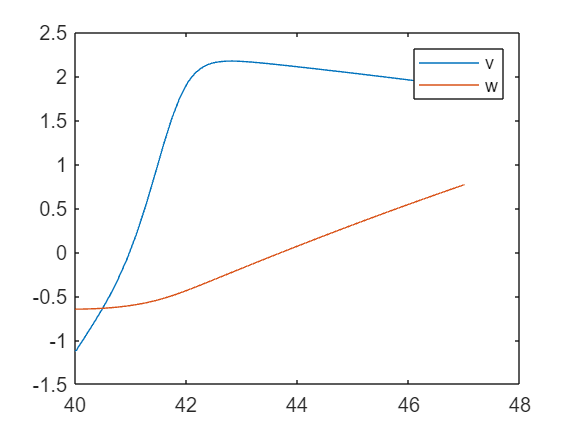

epsilon = 0.08;
a = 1.0;
b = 0.2;
I0 = 1.0;
tStart = 40;
tStop = 47;
I = @(t) I0*(t>tStart).*(t<tStop);


dvdt = @(v,w) v - (1/3)*v^3 - w;
dwdt = @(v,w) epsilon*(v + a - b*w);

dxdt = @(t,x)[dvdt(x(1),x(2))+I(t);
    dwdt(x(1),x(2))];

[T,X] = ode45(dxdt, [40,47], [-1.12969,-.649138]);

figure; clf; hold on; box on;
plot(T,X(:,1));
plot(T,X(:,2));
legend('v','w');

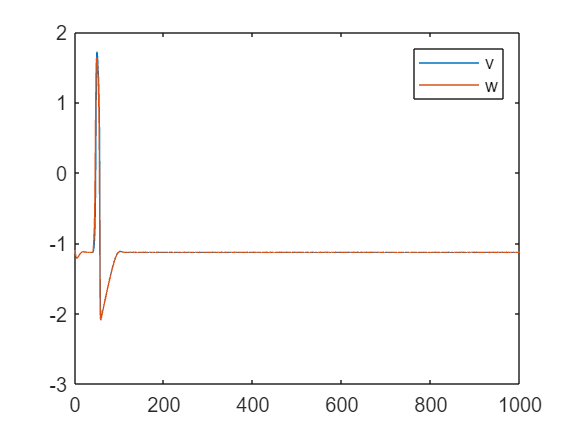

epsilon = 0.08;
a = 1.0;
b = 0.2;
I0 = 1.0;
tStart = 40;
tStop = 47;
I = @(t) I0*(t>tStart).*(t<tStop);

D = 0.9;

dvdt = @(v,w) v - (1/3)*v.^3 - w;
dwdt = @(v,w) epsilon*(v + a - b*w);

dxdt = @(t,x)[dvdt(x(1:10),x(11:20)) + D*([x(2:10);x(1)] -2*x(1:10) + [x(10);x(1:9)] + [0;0;0;1;0;0;0;0;0;0]*I(t));
    dwdt(x(1:10),x(11:20))];

ic = [-1.1*ones(10,1);-0.6*ones(10,1)];

[T,X] = ode45(dxdt, [0,1000], ic);

figure; clf; hold on; box on;
plot(T,X(:,1));
plot(T,X(:,2));
legend('v','w');

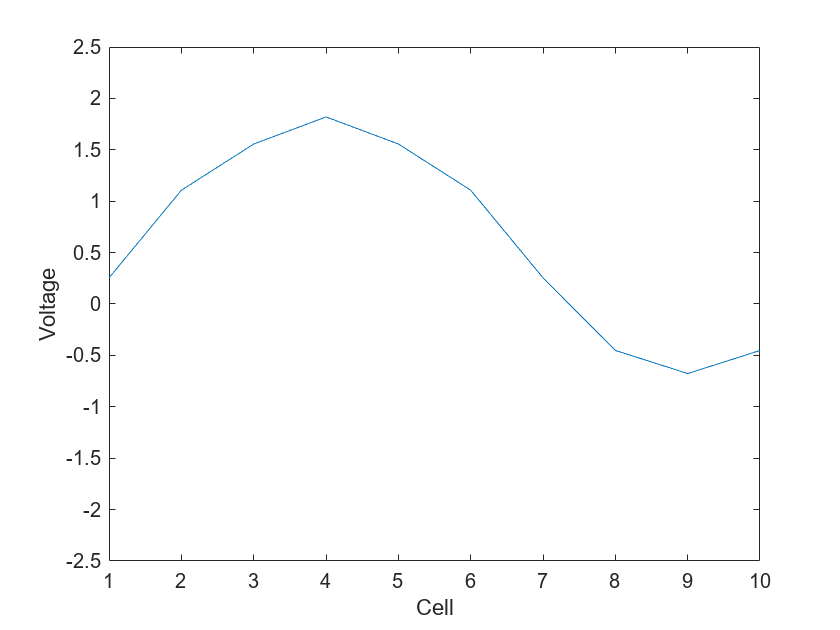


figure(5)
% movie
for nt=1:numel(T)
    figure(5); clf; hold on; box on;
    plot(X(nt,1:10)); 
    set(gca,'ylim', [-2.5,2.5])
    xlabel('Cell');
    ylabel('Voltage')
    drawnow;
end

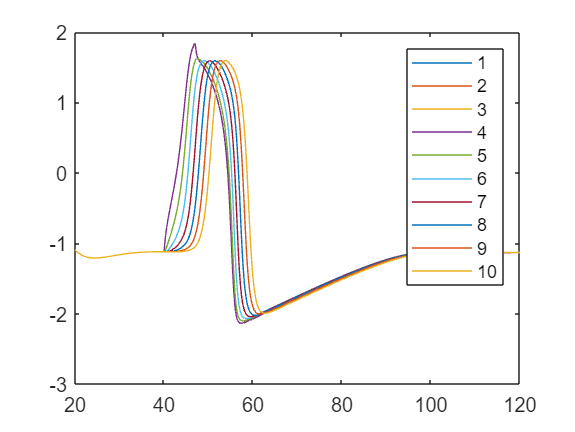

epsilon = 0.08;
a = 1.0;
b = 0.2;
I0 = 1.0;
tStart = 40;
tStop = 47;
I = @(t) I0*(t>tStart).*(t<tStop);

D = 0.9;

dvdt = @(v,w) v - (1/3)*v.^3 - w;
dwdt = @(v,w) epsilon*(v + a - b*w);

iconst = zeros(100,1);
iconst(4) = 1;

dxdt = @(t,x)[dvdt(x(1:100),x(101:200)) + D*([x(2:100);x(1)] -2*x(1:100) + [x(100);x(1:99)] + iconst*I(t));
    dwdt(x(1:100),x(101:200))];

ic = [-1.1*ones(100,1);-0.6*ones(100,1)];

[T,X] = ode45(dxdt, [20,120], ic);

figure; clf; hold on; box on;
for i=1:10
    plot(T,X(:,i));
end
legend('1','2','3','4','5','6','7','8','9','10')

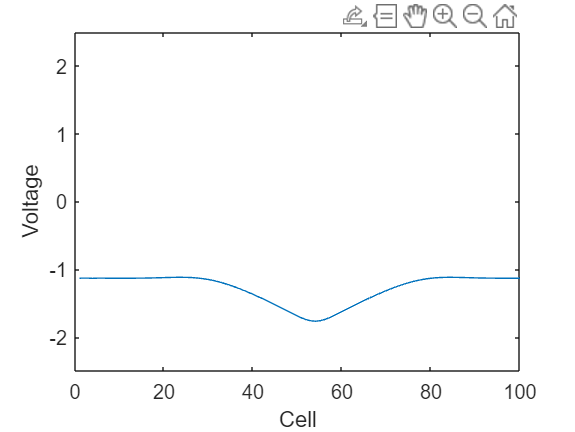


figure(5)
% movie
for nt=1:numel(T)
    figure(5); clf; hold on; box on;
    plot(X(nt,1:100)); 
    set(gca,'ylim', [-2.5,2.5])
    xlabel('Cell');
    ylabel('Voltage')
    drawnow;
end